 %%% given below data estimate he tranfer function
 
 inputdata=[0,1,1,1,1,1,1]
 outputdata=[0,1,1.5,1.87,2.163,2.3971,2.5844]
 %%lav sådan noget her lort i maple, 4 ligninger med 4 ubekendte. 

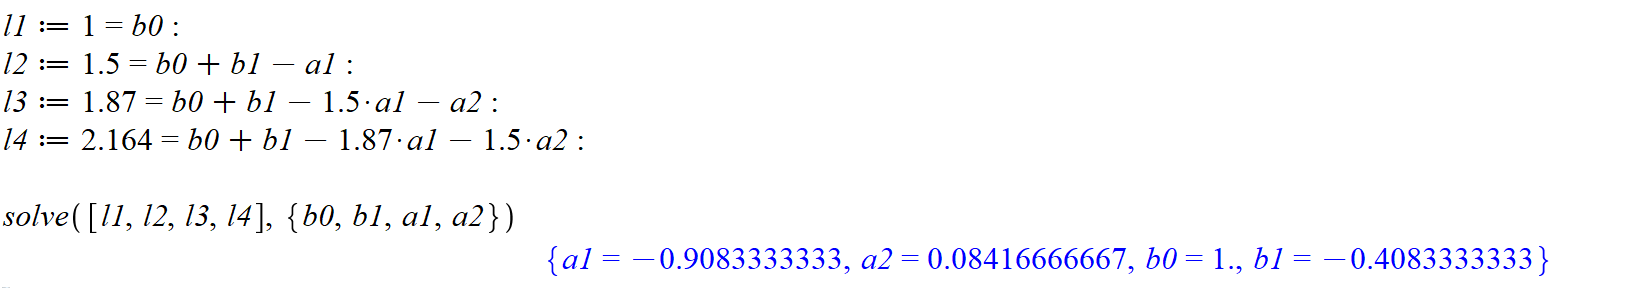 finds the transfer function in the c program

## c kode lort


 
clc;clear all; close all;

k1 = 0.3;
k2 = 0.15;
k3 = 0.6;
k4 = 0.1;
d1 = 0;
d2 = 0;
f = 0;
i1=0;
i2=0;
i = 1;
datain=0;
while(i<100)
        e = datain;
        u1 = e + i1;
        u = k1*f+d2;
        f  = k1 - d1;
        i1 = i1+k4*e;
        i2 = i2+f;
        d1 = k3*i2;
        d2 = k2 *i2;
        output(i) = u;
        i = i + 1;
        datain = 1;
end
figure
hold on
plot(output)
step(tf([3 -5.1 2.16],[1 -1.4 0.4],-1)) %choice 1
step(tf([3 -4.8 1.92],[1 -1.6 0.6],-1)) %choice 2
step(tf([3 -4.6 1.76],[1 -1.7 0.7],-1)) %choice 3
step(tf([2.8 -4.44 1.76],[1 -1.5 0.5],-1))%choice 4
step(tf([3 -4.6 1.76],[1 -1.6 0.63],-1)) %choice 5
legend('C code','Choice 1','Choice 2','Choice 3','Choice 4','Choice 5')

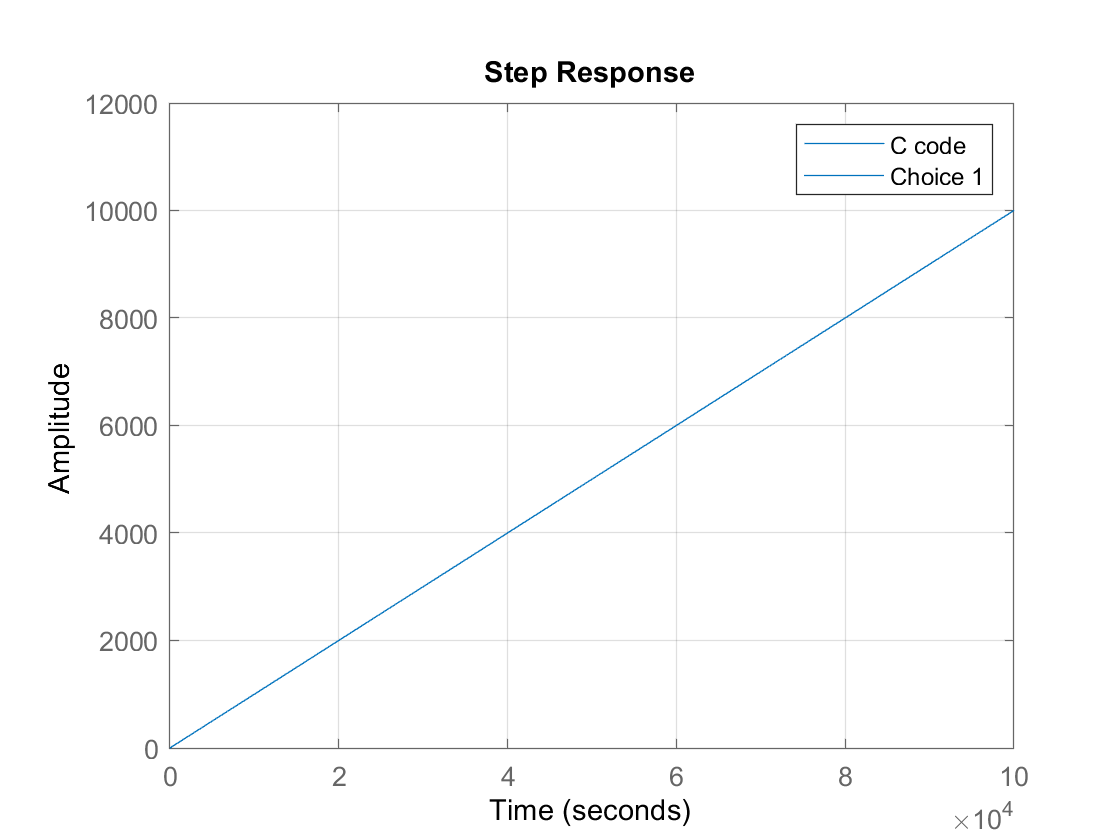

hold off
grid on 

## Frequncy sampling


clc; clear all; close all; 
sysfreq=1/0.01;
nfreq=44;
if 2*nfreq <= sysfreq
    result = nfreq
else 
    result = sysfreq-nfreq
end

result = 44

## h_ad


clc;clear all; close all;
sim('cheat_sheat.slx')

%its now possible to get the transfer fucntion with the dlinmod function

[num,denom]=dlinmod('cheat_sheat')

num =          0    0.0100   -0.0070   -0.0000
    1.0000   -1.6800    0.6860         0
    1.0000   -0.9800         0         0
    1.0000   -1.8300    0.8330         0


denom =     1.0000   -1.6900    0.6930         0



%the transfer function can now be build

Dz=tf([num],[denom],-1)

Error using tf (line 299)
The values of the "Numerator" and "Denominator" properties must be row vectors or cell arrays of row vectors, where each vector is nonempty and containing numeric data. Type "help tf.num" or "help tf.den" for more information.


%now the gain of the transfer fucntion can be found 
%covar er for worst case og minimum
contribution1=abs(sum(num)/sum(denom))*0.5

## large signal analysis


%handler bare om at ændre outport i stedet for inport
clear all;
%Jeg kører bare systemet uden forstyrelser og får hda værdien:
% kan med fordel køre alle på 1 gang. 
sim('cheat_sheat');
[num,denum] = dlinmod('cheat_sheat');
result1 = abs((sum(num(1,:))/sum(denum(:))))

result1 = 2.0000

result2 = abs((sum(num(2,:))/sum(denum(:))))

result2 = 5.0000

result3 = abs((sum(num(3,:))/sum(denum(:))))

result3 = 2.0000

result4 = abs((sum(num(4,:))/sum(denum(:))))

result4 = 1.0000

## position error

% 360 is the range of the potentiometer in meters.
% 2^10 is the bit size of the ad converter.
%  is the DC limit they want us to use. 

delta = ((360/(2^12))*9)

delta = 0.7910

## DC-gain open loop

clear all;
% Vi dividere spændingen fra potentiometeret med den afstand
% potentiometeret kan dreje. Og ganger det med DA converter voltage range
% hvilket her er +-10 så 20 og dividere med ad converter range.
(0-10/1)*(20/10)

ans = -20


%A er delta potentio meter voltage
%B er delta potentiometer range
%C er delta af DA og AD converter bits
(A/B)*(C)

ans = 0.0556

## |e|max 

clc;clear all; close all;
sim('cheat_sheat.slx')

%tjekker sum efter vær gain punkt og ser havd for en er størts i eksemplet
%har vi 5 forskellige gain punkter 

[num,denum] = dlinmod('cheat_sheat');
result1 = (sum(num(1,:))/sum(denum(:)))

result1 = 1.0000

result2 = (sum(num(2,:))/sum(denum(:)))

result2 = 0

result3 = (sum(num(3,:))/sum(denum(:)))

result3 = 1

result4 = (sum(num(4,:))/sum(denum(:)))

result4 = 5.8287e-16

result5 = (sum(num(4,:))/sum(denum(:)))

result5 = 5.8287e-16

%herfra vælges det steørste tal og 1 over dette tal så hvis det største tal
% = 0


## continuer til diskret

Dz=tf([200],[1 40 0 0])


Dz =
 
      200
  ------------
  s^3 + 40 s^2
 
Continuous-time transfer function.



svar=c2d(Dz,0.01,'ZOH') %brug ZOH hvis der kigges på del af systemet tustin hvis det hele systemet


svar =
 
  3.025e-05 z^2 + 0.0001098 z + 2.477e-05
  ---------------------------------------
     z^3 - 2.67 z^2 + 2.341 z - 0.6703
 
Sample time: 0.01 seconds
Discrete-time transfer function.



## Kp given phase margin

% i denne opgave skulle vin finde phase margin på 60 dvs 180-60=120

Dz=tf([4.3*10^-3 3.6*10^-3],[1 -1.6 0.6],0.01)


Dz =
 
  0.0043 z + 0.0036
  -----------------
  z^2 - 1.6 z + 0.6
 
Sample time: 0.01 seconds
Discrete-time transfer function.



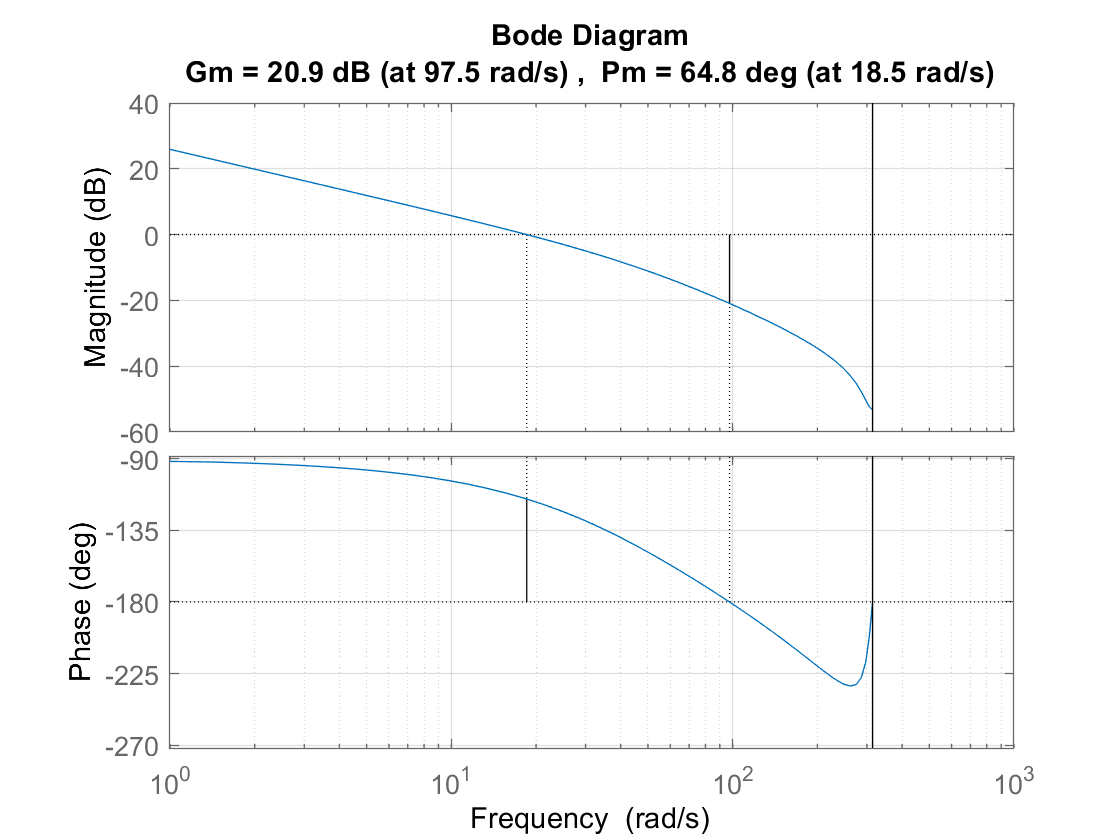

margin(Dz*10)
grid on

%husk !!!!
1/db2mag(-31.26)

ans = 36.5595

## mean power

%% dette eksempel er fra U til h 
clc; clear all;
G0z = minreal(tf([1],[1 -0.9],0.01))


G0z =
 
     1
  -------
  z - 0.9
 
Sample time: 0.01 seconds
Discrete-time transfer function.



[num,denom] = dlinmod('cheat_sheat')

num =     0.5000   -0.4500


denom =     1.0000   -0.9800


Dz1 = minreal(tf([num],[denom],0.01)) % tf from e-u


Dz1 =
 
  0.5 z - 0.45
  ------------
    z - 0.98
 
Sample time: 0.01 seconds
Discrete-time transfer function.



covar(minreal(Dz*(G0z/(1+Dz*G0z))),1/12) %= 0.0271

Undefined function or variable 'Dz'.

## Mean power model determine delta_e^2


%% hvis andre steder i systemet ska findes skal 
% overførings funktionen for hele systemet stadig bruges !
%% eksempel på at finde fra et andet sted i sysemet nede under
% bemærk at Dz er fra hele systemet og Dz2 er fra det punkt
% vi er interreseret i 
clc; clear all;
Dz=tf([0.5 -0.45],[1 -0.98],0.01);
G0z = minreal(tf([1],[1 -0.9],0.01));
[num,denom] = dlinmod('cheat_sheat');
Dz2 = minreal(tf([num],[denom],0.01)); % tf from e-u
minreal(Dz2*(G0z/(1+Dz*G0z)))


ans =
 
    0.5
  --------
  z - 0.48
 
Sample time: 0.01 seconds
Discrete-time transfer function.



covar(minreal(Dz2*(G0z/(1+Dz*G0z))),1/12); %= 0.0271

## product quantization by truncation, DC_lim

% så det handler om at finde overførings funktionerne
% ligesom i mean power model determine delta_e^2 afsnittet
% når overførings funktionerne er fundet lader vi s->1
% dette giver nogen forskellige tal, der skal ses bort fra systemets
% egen overførsings funktion, denne skal kun bruges til at 
% finde de andre, vi skal ikke bruge contribution fra den
Dz1=tf([0.5],[1 -0.48],0.01);

%der skal findes overførings funktioner for alle gain led
% det vides at i denne opgave er 2 af ledende det samme 
% men for en sikkerheds skyld så bare find for alle.

Dz2=tf([1 -0.98],[1 -1.38 0.432],0.01)


Dz2 =
 
        z - 0.98
  --------------------
  z^2 - 1.38 z + 0.432
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Dz2_con=(1-0.98)/(1-1.38+0.432)

Dz2_con = 0.3846


Dz3=tf([2 -3.8 1.8],[1 -2.28 1.674 -0.3888],0.01)


Dz3 =
 
         2 z^2 - 3.8 z + 1.8
  ---------------------------------
  z^3 - 2.28 z^2 + 1.674 z - 0.3888
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Dz3_con=(2-3.8+1.8)/(1-2.28+1.674-0.388)

Dz3_con = 3.7007e-14

%nu kan disse led ligges sammen, der skal ses bort fra Dz1
%som kun er blevet brugt til at finde de andre led 

svar=((Dz2_con*2)+Dz3_con)*0.5

svar = 0.3846

result1 = 3.1000

result2 = 0.9000

result3 = 3.2000

ans = 0.3125

%sum(abs(impulse(3.2))) %matlab kan ikke, men det give 3.2...
sum(abs(impulse(3.1*z^(-1)))) %= 3.1
sum(abs(impulse(Gx4_24))) %= 2.1946
syshel = tf([3.2 -3.1],[1 -0.9],-1)
sum(abs(impulse(syshel))) %= 5.3946      0.1854